
myfolder = "/Users/emiliathoma/Desktop/docu_tables_und_traces_human_thoma"

myfolder = "/Users/emiliathoma/Desktop/docu_tables_und_traces_human_thoma"

filepattern_docu_table = fullfile(myfolder,"*.xlsx")

filepattern_docu_table = "/Users/emiliathoma/Desktop/docu_tables_und_traces_human_thoma/*.xlsx"

filepattern_supra = fullfile(myfolder,"*supra.txt")

filepattern_supra = "/Users/emiliathoma/Desktop/docu_tables_und_traces_human_thoma/*supra.txt"

filepattern_connectivity = fullfile(myfolder,"*connectivity.txt")

filepattern_connectivity = "/Users/emiliathoma/Desktop/docu_tables_und_traces_human_thoma/*connectivity.txt"


filelist_docu_table = dir(filepattern_docu_table);
filelist_supra = dir(filepattern_supra);
filelist_connectivity = dir(filepattern_connectivity);

all_data = struct;

### Einlesen docu_table

for k = 1:length(filelist_docu_table)
    basefilename = filelist_docu_table(k).name;
    fullfilename = fullfile(filelist_docu_table(k).folder, basefilename);
    thisDocuTable = readtable(fullfilename, "VariableNamingRule", "preserve");
    all_data(k).namen= basefilename;
    all_data(k).docutables = thisDocuTable;
end

for k = 1:length(filelist_supra)
    basefilename = filelist_supra(k).name;
    fullfilename = fullfile(filelist_supra(k).folder, basefilename);
    thisSupraTable = table2array(readtable(fullfilename, "VariableNamingRule", "preserve"));
    all_data(k).supra_namen= basefilename;
    all_data(k).supra = thisSupraTable;
    %supratables{k} = thisSupraTable
end



# tcell

variable_names_types = [["cell_ID", "string"]; ...
			["AP_Amplitude", "double"]; ...
			["half_duration_ms", "double"]; ...
            ["AP_time", "double"]; ...
            ["threshold_timpoint", "double"]; ...
            ["threshold_amplitude", "double"]; ...
            ["peak_amplitude", "double"]; ...
            ["resting_pot", "double"]; ...
            ["freq_Hz_minus300pA_0ms_100ms", "double"]; ...
            ["Ap_number_minus300pA_0ms_100ms", "double"]; ...
            ["freq_Hz_minus300pA_200ms_400ms", "double"]; ...
            ["Ap_number_minus300pA_200ms_400ms", "double"]; ...
            ["freq_Hz_minus200pA_0ms_100ms", "double"]; ...
            ["Ap_number_minus200pA_0ms_100ms", "double"]; ...
            ["freq_Hz_minus200pA_200ms_400ms", "double"]; ...
            ["Ap_number_minus200pA_200ms_400ms", "double"]; ...
            ["freq_Hz_minus150pA_0ms_100ms", "double"]; ...
            ["Ap_number_minus150pA_0ms_100ms", "double"]; ...
            ["freq_Hz_minus150pA_200ms_400ms", "double"]; ...
            ["Ap_number_minus150pA_200ms_400ms", "double"]; ...
            ["freq_Hz_minus100pA_0ms_100ms", "double"]; ...
            ["Ap_number_minus100pA_0ms_100ms", "double"]; ...
            ["freq_Hz_minus100pA_200ms_400ms", "double"]; ...
            ["Ap_number_minus100pA_200ms_400ms", "double"]; ...
            ["freq_Hz_minus50pA_0ms_100ms", "double"]; ...
            ["Ap_number_minus50pA_0ms_100ms", "double"]; ...
            ["freq_Hz_minus50pA_200ms_400ms", "double"]; ...
            ["Ap_number_minus50pA_200ms_400ms", "double"]; ...
            ["freq_Hz_0pA_0ms_100ms", "double"]; ...
            ["Ap_number_0pA_0ms_100ms", "double"]; ...
            ["freq_Hz_0pA_200ms_400ms", "double"]; ...
            ["Ap_number_0pA_200ms_400ms", "double"]; ...
            ["freq_Hz_50pA_0ms_100ms", "double"]; ...
            ["Ap_number_50pA_0ms_100ms", "double"]; ...
            ["freq_Hz_50pA_200ms_400ms", "double"]; ...
            ["Ap_number_50pA_200ms_400ms", "double"]; ...
            ["freq_Hz_100pA_0ms_100ms", "double"]; ...
            ["Ap_number_100pA_0ms_100ms", "double"]; ...
            ["freq_Hz_100pA_200ms_400ms", "double"]; ...
            ["Ap_number_100pA_200ms_400ms", "double"]; ...
            ["freq_Hz_150pA_0ms_100ms", "double"]; ...
            ["Ap_number_150pA_0ms_100ms", "double"]; ...
            ["freq_Hz_150pA_200ms_400ms", "double"]; ...
            ["Ap_number_150pA_200ms_400ms", "double"]; ...
            ["freq_Hz_200pA_0ms_100ms", "double"]; ...
            ["Ap_number_200pA_0ms_100ms", "double"]; ...
            ["freq_Hz_200pA_200ms_400ms", "double"]; ...
            ["Ap_number_200pA_200ms_400ms", "double"]; ...
            ["freq_Hz_250pA_0ms_100ms", "double"]; ...
            ["Ap_number_250pA_0ms_100ms", "double"]; ...
            ["freq_Hz_250pA_200ms_400ms", "double"]; ...
            ["Ap_number_250pA_200ms_400ms", "double"]; ...
            ["freq_Hz_300pA_0ms_100ms", "double"]; ...
            ["Ap_number_300pA_0ms_100ms", "double"]; ...
            ["freq_Hz_300pA_200ms_400ms", "double"]; ...
            ["Ap_number_300pA_200ms_400ms", "double"]; ...
            ["freq_Hz_350pA_0ms_100ms", "double"]; ...
            ["Ap_number_350pA_0ms_100ms", "double"]; ...
            ["freq_Hz_350pA_200ms_400ms", "double"]; ...
            ["Ap_number_350pA_200ms_400ms", "double"]; ...
            ["freq_Hz_400pA_0ms_100ms", "double"]; ...
            ["Ap_number_400pA_0ms_100ms", "double"]; ...
            ["freq_Hz_400pA_200ms_400ms", "double"]; ...
            ["Ap_number_400pA_200ms_400ms", "double"]; ...
            ["freq_Hz_450pA_0ms_100ms", "double"]; ...
            ["Ap_number_450pA_0ms_100ms", "double"]; ...
            ["freq_Hz_450pA_200ms_400ms", "double"]; ...
            ["Ap_number_450pA_200ms_400ms", "double"]; ...
            ["freq_Hz_500pA_0ms_100ms", "double"]; ...
            ["Ap_number_500pA_0ms_100ms", "double"]; ...
            ["freq_Hz_500pA_200ms_400ms", "double"]; ...
            ["Ap_number_500pA_200ms_400ms", "double"]; ...
            ["freq_Hz_550pA_0ms_100ms", "double"]; ...
            ["Ap_number_550pA_0ms_100ms", "double"]; ...
            ["freq_Hz_550pA_200ms_400ms", "double"]; ...
            ["Ap_number_550pA_200ms_400ms", "double"]; ...
            ["freq_Hz_600pA_0ms_100ms", "double"]; ...
            ["Ap_number_600pA_0ms_100ms", "double"]; ...
            ["freq_Hz_600pA_200ms_400ms", "double"]; ...
            ["Ap_number_600pA_200ms_400ms", "double"]; ...
            ["freq_Hz_700pA_0ms_100ms", "double"]; ...
            ["Ap_number_700pA_0ms_100ms", "double"]; ...
            ["freq_Hz_700pA_200ms_400ms", "double"]; ...
            ["Ap_number_700pA_200ms_400ms", "double"]; ...
            ["freq_Hz_800pA_0ms_100ms", "double"]; ...
            ["Ap_number_800pA_0ms_100ms", "double"]; ...
            ["freq_Hz_800pA_200ms_400ms", "double"]; ...
            ["Ap_number_800pA_200ms_400ms", "double"]; ...
            ["freq_Hz_900pA_0ms_100ms", "double"]; ...
            ["Ap_number_900pA_0ms_100ms", "double"]; ...
            ["freq_Hz_900pA_200ms_400ms", "double"]; ...
            ["Ap_number_900pA_200ms_400ms", "double"]; ...
            ["input_resistance", "double"]; ...
            ["downstroke_mVperms", "double"]; ...
            ["upstroke_mVperms", "double"]; ...
            ["hyperpolarisation", "double"]; ...
            ["half_amplitude", "double"]];

% Make table using fieldnames & value types from above
tcell = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));


for i=1:size(all_data,2) %durch alle tables durch iterieren
    for channel_n = 1:10 %durch alle 10 channel iterieren
        if all_data(i).docutables{channel_n,2} ==1
            S=strsplit(all_data(i).supra_namen,"_");
            S=strjoin([S(2), S(3)],"_");
            length(tcell.cell_ID)+1
            cellID = append(S,"_C", string(channel_n)); %je nachdem welcher Manipulator ==1, also included war
            tcell.cell_ID(length(tcell.cell_ID)+1,1)=cellID;
        end
    end
end

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14

ans = 15

ans = 16

ans = 17

ans = 18

ans = 19

ans = 20

% k=1;
% for i=1:size(all_data,2)
%     for channel_n = 1:10 %durch alle 10 channel iterieren
%         if all_data(i).docutables{channel_n,2} ==1
%             data=all_data(i).supra(:,channel_n+1);
%             stim_starts = [4.8e5, 5e5];
%             %if i==2 && channel_n==8
%             %    stim_starts = [4.805e5, 5e5];
%             %end
% 
%             stim_duration = 1*20e3;
%             trace_segment = data(stim_starts(1):stim_starts(2),1);
%             % figure
%             % plot(trace_segment)
% 
%             diff_trace_segment = diff(trace_segment);
%             %downstroke in mV/ms
%             max_downstroke_tik = min(diff_trace_segment);
%             max_downstroke = max_downstroke_tik*20;
%             try
%             tcell.downstroke_mVperms(k)=max_downstroke;
% 
%             diff_threshold = 2;
%             AP_time = find(diff_trace_segment>diff_threshold, 1, "first");
% 
% 
% 
%             % figure
%             % % plot(diff_trace_segment, 'o')
%             % % yline(2)
%             % try
%             % xline(AP_time)
%             % end
%             %extract the AP
%             if AP_time < 50
%             trace_AP = trace_segment(1:AP_time+100);
%             else
%             trace_AP = trace_segment(AP_time-50:AP_time+100);
%             end
%             tcell.AP_time(k)=AP_time;
%             %threshold amplitude
%             try
%             threshold_timpoint = find(diff(trace_AP)>diff_threshold, 1, 'first');
%             tcell.threshold_timpoint(k)=threshold_timpoint;
%             threshold_amplitude = trace_AP(threshold_timpoint);
%             tcell.threshold_amplitude(k)=threshold_amplitude;
%             end
%             %get the peak amplitude
%             peak_amplitude = max(trace_AP);
%             tcell.peak_amplitude(k) = peak_amplitude;
%             %AP amplitude
%             ap_amplitude = peak_amplitude-threshold_amplitude;
%             tcell.AP_Amplitude(k)=ap_amplitude;
%             %Hyper polar
%             try
%             trace_AP_hyper_timeframe = trace_segment(AP_time-10:AP_time+100);
%             hyperpolarisation = min(trace_AP_hyper_timeframe);
%             tcell.hyperpolarisation(k)=hyperpolarisation;
%             end
%             %ap half duration:
%             try
%             half_amplitude = threshold_amplitude + (ap_amplitude/2);
%             tcell.half_amplitude(k)=half_amplitude;
%             first_crossing_of_half_amplitude = find(trace_AP>half_amplitude,1,"first");
%             first_negative_crossing_of_half_amplitude = ...
%                 find(trace_AP(first_crossing_of_half_amplitude:end)<half_amplitude,1, "first") + first_crossing_of_half_amplitude;
%             %half duration
%             half_duration = first_negative_crossing_of_half_amplitude-first_crossing_of_half_amplitude;
%             tcell.half_duration_ms(k)=half_duration/20;
%             end
%             end
%             %input resistance
%             stim_current_starts = [0.8e5, 1e5];
%             stim_current = [-150e-12, -100e-12, -50e-12];
%             Rin_sum=0;
%             Rins={};
%             Rin_avg=0;
%             for stim_i = 1: 3
%                 trace_segment_res = all_data(i).supra(stim_current_starts(1):stim_current_starts(2),channel_n+1);
%                 diff_trace_segment_res = diff(trace_segment_res);
%                 diff_threshold = 2;
%                 AP_time_res = find(diff_trace_segment_res>diff_threshold, 1, "first");
%                 if isempty(AP_time_res)==1
%                     steadystate=mean(trace_segment_res);
%                     basesegment=(all_data(1).supra(stim_current_starts(1)-20000:stim_current_starts(2)-20000,channel_n+1));
%                     baseline=mean(basesegment);
%                 end
%                 stim_current_starts = stim_current_starts + [0.4e5, 0.4e5];
%                 dV=steadystate-baseline;
%                 Rin=(dV)*10^-3/stim_current(stim_i);
%                 Rins=[Rins, Rin];
%                 Rin_sum=Rin_sum+Rin;
%             end
%             Rin_avg=Rin_sum/stim_i;
%             %Tabele mit input resistances pro manip.
%             Rins;
%             tcell.input_resistance(k)=Rin_avg;
%             %später in MegaOhmen angeben!!!
% 
% 
%             %freq
%             % figure
%             % plot(trace_segment)
% 
%             stim_starts_1 = [0.4e5, 0.6e5];
%             stim_starts_2 = [0.8e5, 1e5];
%             stim_starts_3 = [1.2e5, 1.4e5];
%             stim_starts_4 = [1.6e5, 1.8e5];
%             stim_starts_5 = [2e5, 2.2e5];
%             stim_starts_6 = [2.4e5, 2.6e5];
%             stim_starts_7 = [2.8e5, 3e5];
%             stim_starts_8 = [3e2, 3.4e5];
%             stim_starts_9 = [3.6e5, 3.8e5];
%             stim_starts_10 = [4e5, 4.2e5];
%             stim_starts_11 = [5.6e5, 5.8e5];
%             stim_starts_12 = [6e5, 6.2e5];
%             stim_starts_13 = [6.4e5, 6.6e5];
%             stim_starts_14 = [6.8e5, 7e5];
%             stim_starts_15 = [7.2e5, 7.4e5];
%             stim_starts_16 = [7.6e5, 7.8e5];
%             stim_starts_17 = [8e5, 8.2e5];
% 
% 

% 
%             try
%             Ap_number=1;
%             First_AP_Time=AP_time;
% 
%             AP_time_freq=AP_time+100;
%             while AP_time_freq<=2000
%                 freq_segment = data(stim_starts(1)+AP_time_freq:stim_starts(2),1);
%                 stim_starts(1)+AP_time_freq;
%                 diff_freq_segment = diff(freq_segment);
%                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
%                 if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
%                 Ap_number=Ap_number+1;
%                 Last_AP_Time=AP_time_freq-100;
%                 end 
%             end
%             %tik in sekunde
%             end
%             try
%             period = (Last_AP_Time-First_AP_Time)*0.00005;
%             frq_per_0_100 = Ap_number/period;
%             tcell.freq_Hz_0ms_100ms(k)=frq_per_0_100;
%             Ap_number=0;
%             AP_time_freq=4000;
%             First_AP_Time=4000;
%             while AP_time_freq<=8000
%                  freq_segment = data(stim_starts(1)+AP_time_freq:stim_starts(2),1);
%                  stim_starts(1)+AP_time_freq;
%                  diff_freq_segment = diff(freq_segment);
%                  AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
%                  if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
%                  Ap_number=Ap_number+1;
%                  Last_AP_Time=AP_time_freq-100;
%                  end 
%              end
%              period = (Last_AP_Time-First_AP_Time)*0.00005;
%              frq_per_200_400 = Ap_number/period;
%             tcell.freq_Hz_200ms_400ms(k)=frq_per_200_400;
%             end
%             % figure
%             % plot(trace_AP, "Color", "k", "LineWidth",2)
%             %try
%             %yline(threshold_amplitude)
%             %xline(threshold_timpoint)
%             %yline(peak_amplitude)
%             %yline(half_amplitude)
%             %xline(first_crossing_of_half_amplitude)
%             %xline(first_negative_crossing_of_half_amplitude)   
%             k=k+1
% 
%         end
%     end
% end 

AP_time = 1583

stim_current_starts =       160000      180000


stim_current_starts =       200000      220000


stim_current_starts =       240000      260000


stim_current_starts =       280000      300000


stim_current_starts =       320000      340000


Rin_avg = -Inf

i = 1

k = 1

channel_n = 1

trace_AP =   -40.7715
  -40.6799
  -40.6799
  -40.6799
  -40.5884
  -40.5579
  -40.5273
  -40.4968
  -40.4663
  -40.4358


first_negative_crossing_of_half_amplitude = 82

stim_current_starts =       158000      182000


stim_i = 1

stim_current_starts =       198000      222000


stim_i = 2

stim_current_starts =       238000      262000


stim_i = 3

stim_current_starts =       278000      302000


stim_i = 4

stim_current_starts =       318000      342000


stim_i = 5

freqs =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   44.2478   53.8117   44.2968


maxfreq_time = 17

maxfreq_time = 680000

max_freq_segment =   -76.5381
  -76.4771
  -76.5076
  -76.5686
  -76.4771
  -76.4771
  -76.5686
  -76.4771
  -76.5076
  -76.5076


abs_max_freq = 63.9386

type = 'undefined Neuron'

k = 2

AP_time = 1022

stim_current_starts =       160000      180000


stim_current_starts =       200000      220000


stim_current_starts =       240000      260000


stim_current_starts =       280000      300000


stim_current_starts =       320000      340000


Rin_avg = -Inf

i = 1

k = 2

channel_n = 4

trace_AP =   -44.5557
  -44.5251
  -44.4946
  -44.4031
  -44.3726
  -44.3420
  -44.3115
  -44.2810
  -44.2810
  -44.2505


first_negative_crossing_of_half_amplitude = 75

stim_current_starts =       158000      182000


stim_i = 1

stim_current_starts =       198000      222000


stim_i = 2

stim_current_starts =       238000      262000


stim_i = 3

stim_current_starts =       278000      302000


stim_i = 4

stim_current_starts =       318000      342000


stim_i = 5

freqs =          0         0         0         0         0         0         0         0         0         0         0         0         0         0   46.0829   66.4452   74.7198   54.7945


maxfreq_time = 17

maxfreq_time = 680000

max_freq_segment =   -72.6318
  -72.6624
  -72.6318
  -72.6013
  -72.6318
  -72.6318
  -72.5708
  -72.6318
  -72.6013
  -72.6013


abs_max_freq = 74.7198

type = 'undefined Neuron'

k = 3

AP_time = 1817

stim_current_starts =       160000      180000


stim_current_starts =       200000      220000


stim_current_starts =       240000      260000


stim_current_starts =       280000      300000


stim_current_starts =       320000      340000


Rin_avg = Inf

i = 1

k = 3

channel_n = 8

trace_AP =   -45.1660
  -45.0439
  -44.9829
  -44.9829
  -45.0134
  -44.9524
  -44.9219
  -44.9219
  -44.9829
  -44.9219


first_negative_crossing_of_half_amplitude = 79

stim_current_starts =       158000      182000


stim_i = 1

stim_current_starts =       198000      222000


stim_i = 2

stim_current_starts =       238000      262000


stim_i = 3

stim_current_starts =       278000      302000


stim_i = 4

stim_current_starts =       318000      342000


stim_i = 5

freqs =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   49.5458   57.4713


maxfreq_time = 18

maxfreq_time = 720000

max_freq_segment =   -73.6389
  -73.7610
  -73.7000
  -73.7305
  -73.6389
  -73.7305
  -73.6694
  -73.7305
  -73.7305
  -73.8220


abs_max_freq = 68.4932

type = 'undefined Neuron'

k = 4

AP_time = 446

stim_current_starts =       160000      180000


stim_current_starts =       200000      220000


stim_current_starts =       240000      260000


stim_current_starts =       280000      300000


stim_current_starts =       320000      340000


Rin_avg = -Inf

i = 2

k = 4

channel_n = 1

trace_AP =   -45.3186
  -45.4102
  -45.2271
  -45.1355
  -45.0439
  -45.0439
  -44.9524
  -44.8303
  -44.6777
  -44.5557


first_negative_crossing_of_half_amplitude = 76

stim_current_starts =       158000      182000


stim_i = 1

stim_current_starts =       198000      222000


stim_i = 2

stim_current_starts =       238000      262000


stim_i = 3

stim_current_starts =       278000      302000


stim_i = 4

stim_current_starts =       318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0         0         0         0         0   49.2207   52.7241   61.9195   68.7285   53.1350   56.6572   59.5948


maxfreq_time = 15

maxfreq_time = 600000

max_freq_segment = 24001×1
  -76.7517
  -76.7822
  -76.8127
  -76.7212
  -76.7212
  -76.8433
  -76.7822
  -76.7212
  -76.7517
  -76.9043


abs_max_freq = 73.7101

type = 'undefined Neuron'

k = 5

AP_time = 378

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = -Inf

i = 2

k = 5

channel_n = 4

trace_AP = 151×1
  -48.4314
  -48.3704
  -48.3093
  -48.1873
  -48.1567
  -48.0652
  -48.0347
  -47.9431
  -47.8821
  -47.7600


first_negative_crossing_of_half_amplitude = 76

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0         0         0         0   50.9771   68.7285   61.6333   62.5489   70.9849   68.4932   82.4176   79.9087


maxfreq_time = 17

maxfreq_time = 680000

max_freq_segment = 24001×1
  -75.9888
  -76.0193
  -76.0193
  -76.0803
  -75.9888
  -75.9888
  -75.9888
  -75.9583
  -75.9888
  -76.0193


abs_max_freq = 92.1053

type = 'undefined Neuron'

k = 6

AP_time = 124

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = Inf

i = 3

k = 6

channel_n = 1

trace_AP = 151×1
  -56.2134
  -55.9998
  -55.7861
  -55.6030
  -55.5115
  -55.2979
  -55.1147
  -54.9622
  -54.8706
  -54.7180


first_negative_crossing_of_half_amplitude = 64

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0         0   88.3652   81.6993   90.9091  104.2270  120.1923  132.4503  140.3509  148.6564  155.8753  163.5514


maxfreq_time = 18

maxfreq_time = 720000

max_freq_segment = 24001×1
  -72.5403
  -72.5098
  -72.6013
  -72.5098
  -72.5403
  -72.5098
  -72.6013
  -72.5403
  -72.5708
  -72.6013


abs_max_freq = 177.1872

type = 'fastspiking IN'

k = 7

AP_time = 64

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = -Inf

i = 3

k = 7

channel_n = 4

trace_AP = 151×1
  -56.5796
  -56.5491
  -56.5796
  -56.5796
  -56.6101
  -56.6101
  -56.6101
  -56.6406
  -56.6101
  -56.6101


stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0  126.1034  124.4555  147.6015  159.3625  157.2052  237.1542         0         0         0         0         0


maxfreq_time = 13

maxfreq_time = 520000

max_freq_segment = 24001×1
  -56.3965
  -56.3965
  -56.4270
  -56.3965
  -56.3965
  -56.4270
  -56.3965
  -56.3965
  -56.4270
  -56.4270


abs_max_freq = 237.1542

type = 'fastspiking IN'

k = 8

AP_time = 92

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = Inf

i = 4

k = 8

channel_n = 4

trace_AP = 151×1
  -49.0112
  -48.9807
  -48.8586
  -48.8586
  -48.9502
  -48.9807
  -49.0417
  -49.0417
  -49.1028
  -49.1028


first_negative_crossing_of_half_amplitude = 69

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0   44.6097   82.5472   81.8235   99.0712  113.4430  133.4951  146.0674  164.0305  181.6118  190.4762  202.7027  184.0138


maxfreq_time = 17

maxfreq_time = 680000

max_freq_segment = 24001×1
  -50.1404
  -50.1099
  -50.1099
  -50.0793
  -50.1099
  -50.0793
  -50.0488
  -50.0488
  -50.0793
  -50.1099


abs_max_freq = 202.7027

type = 'fastspiking IN'

k = 9

AP_time = 184

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = -Inf

i = 4

k = 9

channel_n = 8

trace_AP = 151×1
  -69.6106
  -69.0613
  -68.6340
  -68.1458
  -67.8101
  -67.3218
  -66.9250
  -66.5283
  -66.1621
  -65.8264


first_negative_crossing_of_half_amplitude = 68

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0   46.1894   76.1035   98.1767  115.3107  136.7309  144.9275  154.6698  159.7262  168.7764  171.2329  176.3668


maxfreq_time = 18

maxfreq_time = 720000

max_freq_segment = 24001×1
  -78.2776
  -78.3081
  -78.2471
  -78.2776
  -78.2471
  -78.3386
  -78.3081
  -78.2776
  -78.2471
  -78.2776


abs_max_freq = 180.3833

type = 'fastspiking IN'

k = 10

AP_time = 98

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = Inf

i = 5

k = 10

channel_n = 4

trace_AP = 151×1
  -47.1191
  -47.1191
  -47.1497
  -47.1802
  -47.1802
  -47.2107
  -47.2412
  -47.2412
  -47.2412
  -47.2412


first_negative_crossing_of_half_amplitude = 105

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0   53.4045   56.4972   57.2246   61.1995         0         0         0         0         0         0         0


maxfreq_time = 11

maxfreq_time = 440000

max_freq_segment = 24001×1
  -46.7834
  -46.7834
  -46.7834
  -46.7834
  -46.7834
  -46.7834
  -46.7834
  -46.7834
  -46.7834
  -46.7529


abs_max_freq = 61.1995

type = 'undefined Neuron'

k = 11

AP_time = 136

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = Inf

i = 5

k = 11

channel_n = 8

trace_AP = 151×1
  -41.7175
  -41.6870
  -41.7175
  -41.6870
  -41.7175
  -41.6565
  -41.7786
  -41.7786
  -41.7175
  -41.7786


first_negative_crossing_of_half_amplitude = 65

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0   62.5782   75.9013   99.2556  112.3596  127.0208  134.1463  147.5108  161.2903  161.5695  173.0104  175.8499  179.3186


maxfreq_time = 18

maxfreq_time = 720000

max_freq_segment = 24001×1
  -40.7410
  -40.8020
  -40.8020
  -40.8630
  -40.8325
  -40.8020
  -40.8020
  -40.8020
  -40.8630
  -40.8936


abs_max_freq = 205.1282

type = 'fastspiking IN'

k = 12

AP_time = 169

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = -Inf

i = 5

k = 12

channel_n = 9

trace_AP = 151×1
  -48.2178
  -48.2788
  -48.2483
  -48.2483
  -48.2483
  -48.2483
  -48.2483
  -48.2483
  -48.2178
  -48.2483


first_negative_crossing_of_half_amplitude = 79

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0   45.2489   58.6166   75.9494   95.4329  109.0661  118.4211  140.8451  168.4211  177.3836  209.0592  216.6065         0


maxfreq_time = 17

maxfreq_time = 680000

max_freq_segment = 24001×1
  -52.0325
  -52.0935
  -52.0935
  -52.1240
  -52.1240
  -52.1240
  -52.1240
  -52.0935
  -52.1545
  -52.1240


abs_max_freq = 216.6065

type = 'fastspiking IN'

k = 13

AP_time = 78

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = -Inf

i = 6

k = 13

channel_n = 3

trace_AP = 151×1
  -63.5986
  -63.6292
  -63.6292
  -63.5681
  -63.5376
  -63.5681
  -63.5681
  -63.5681
  -63.5681
  -63.5376


first_negative_crossing_of_half_amplitude = 63

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0   90.8059  124.9290  148.1481  161.8497  190.4762  142.6873  132.0528  129.7935  135.8234  135.3638  140.9278


maxfreq_time = 12

maxfreq_time = 480000

max_freq_segment = 24001×1
  -63.7512
  -63.7512
  -63.7207
  -63.7512
  -63.7207
  -63.7207
  -63.7512
  -63.7512
  -63.7512
  -63.7512


abs_max_freq = 190.4762

type = 'fastspiking IN'

k = 14


AP_time =

  0×1 empty double column vector



stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = -Inf

i = 6

k = 14

channel_n = 4


trace_AP =

  0×1 empty double column vector



stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


maxfreq_time = 1×18
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


maxfreq_time = 1×18
       40000       80000      120000      160000      200000      240000      280000      320000      360000      400000      440000      480000      520000      560000      600000      640000      680000      720000


max_freq_segment = 24001×1
  -11.9629
  -11.9934
  -11.9629
  -12.0239
  -11.9934
  -11.9934
  -11.9934
  -11.9934
  -12.0239
  -12.0239


abs_max_freq = 0

type = 'undefined Neuron'

k = 15

AP_time = 249

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = -Inf

i = 6

k = 15

channel_n = 8

trace_AP = 151×1
  -47.7600
  -47.5464
  -47.4243
  -47.1802
  -47.1191
  -46.9055
  -46.7834
  -46.6614
  -46.4783
  -46.3562


first_negative_crossing_of_half_amplitude = 61

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0         0         0         0   62.0155   81.5217  102.1711  120.4819  130.1005  144.6655  160.0000  170.3163


maxfreq_time = 18

maxfreq_time = 720000

max_freq_segment = 24001×1
  -63.0798
  -63.0798
  -63.1409
  -63.1104
  -63.1409
  -63.1714
  -63.1409
  -63.0798
  -63.0798
  -63.1104


abs_max_freq = 184.7575

type = 'fastspiking IN'

k = 16

AP_time = 44

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = -Inf

i = 7

k = 16

channel_n = 3

trace_AP = 144×1
  -70.4041
  -70.4651
  -70.4041
  -70.4041
  -70.4651
  -70.4346
  -70.4346
  -70.4651
  -70.4956
  -70.4956


first_negative_crossing_of_half_amplitude = 121

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0   84.5921  126.3642  158.7302  179.7753  163.5514  142.3098  132.6700  142.2644         0         0         0


maxfreq_time = 11

maxfreq_time = 440000

max_freq_segment = 24001×1
  -70.4956
  -70.4651
  -70.4956
  -70.4956
  -70.4956
  -70.4651
  -70.4651
  -70.4651
  -70.4651
  -70.4346


abs_max_freq = 179.7753

type = 'fastspiking IN'

k = 17

AP_time = 123

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = -Inf

i = 7

k = 17

channel_n = 8

trace_AP = 151×1
  -67.5049
  -67.5049
  -67.5964
  -67.5659
  -67.5354
  -67.5964
  -67.5049
  -67.5354
  -67.5659
  -67.5964


stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0         0         0         0   88.7574  135.3638  162.6016  177.9359  207.4689  192.3077  178.8909  172.0430


maxfreq_time = 15

maxfreq_time = 600000

max_freq_segment = 24001×1
  -71.3501
  -71.2891
  -71.3196
  -71.2891
  -71.2585
  -71.2585
  -71.3196
  -71.2585
  -71.1975
  -71.1975


abs_max_freq = 207.4689

type = 'fastspiking IN'

k = 18

AP_time = 259

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = Inf

i = 7

k = 18

channel_n = 9

trace_AP = 151×1
  -38.1470
  -38.0859
  -37.9639
  -37.9028
  -37.8418
  -37.7502
  -37.6587
  -37.5671
  -37.5366
  -37.4451


first_negative_crossing_of_half_amplitude = 73

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   51.9031   51.1182   57.3888


maxfreq_time = 18

maxfreq_time = 720000

max_freq_segment = 24001×1
  -42.3584
  -42.3279
  -42.4194
  -42.3889
  -42.3584
  -42.3889
  -42.3889
  -42.4194
  -42.3584
  -42.3584


abs_max_freq = 74.9625

type = 'undefined Neuron'

k = 19

AP_time = 183

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = Inf

i = 8

k = 19

channel_n = 4

trace_AP = 151×1
  -38.1470
  -38.0554
  -38.0249
  -37.9028
  -37.7808
  -37.6587
  -37.5366
  -37.4451
  -37.2620
  -37.2009


first_negative_crossing_of_half_amplitude = 64

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0         0         0   42.1941   49.3523   60.5144   65.4879   73.0816   81.0263   87.0106   90.0901   99.0099


maxfreq_time = 18

maxfreq_time = 720000

max_freq_segment = 24001×1
  -57.2815
  -57.2205
  -57.1899
  -57.2205
  -57.2815
  -57.2815
  -57.2510
  -57.2815
  -57.2815
  -57.2815


abs_max_freq = 145.0893

type = 'non fastspking IN'

k = 20

AP_time = 155

stim_current_starts = 1×2
      160000      180000


stim_current_starts = 1×2
      200000      220000


stim_current_starts = 1×2
      240000      260000


stim_current_starts = 1×2
      280000      300000


stim_current_starts = 1×2
      320000      340000


Rin_avg = -Inf

i = 8

k = 20

channel_n = 8

trace_AP = 151×1
  -55.0232
  -55.0232
  -55.0232
  -55.0232
  -54.9622
  -55.0537
  -55.0537
  -54.9622
  -55.0537
  -55.0537


first_negative_crossing_of_half_amplitude = 64

stim_current_starts = 1×2
      158000      182000


stim_i = 1

stim_current_starts = 1×2
      198000      222000


stim_i = 2

stim_current_starts = 1×2
      238000      262000


stim_i = 3

stim_current_starts = 1×2
      278000      302000


stim_i = 4

stim_current_starts = 1×2
      318000      342000


stim_i = 5

freqs = 1×18
         0         0         0         0         0         0         0         0         0   81.6803   94.0228  107.3986  115.6069  124.5330  128.5047  138.5681  145.8080  149.3395


maxfreq_time = 18

maxfreq_time = 720000

max_freq_segment = 24001×1
  -61.0962
  -61.0657
  -61.0962
  -61.0657
  -61.0352
  -61.0046
  -61.0352
  -61.0657
  -60.9741
  -60.9741


abs_max_freq = 176.2632

type = 'fastspiking IN'

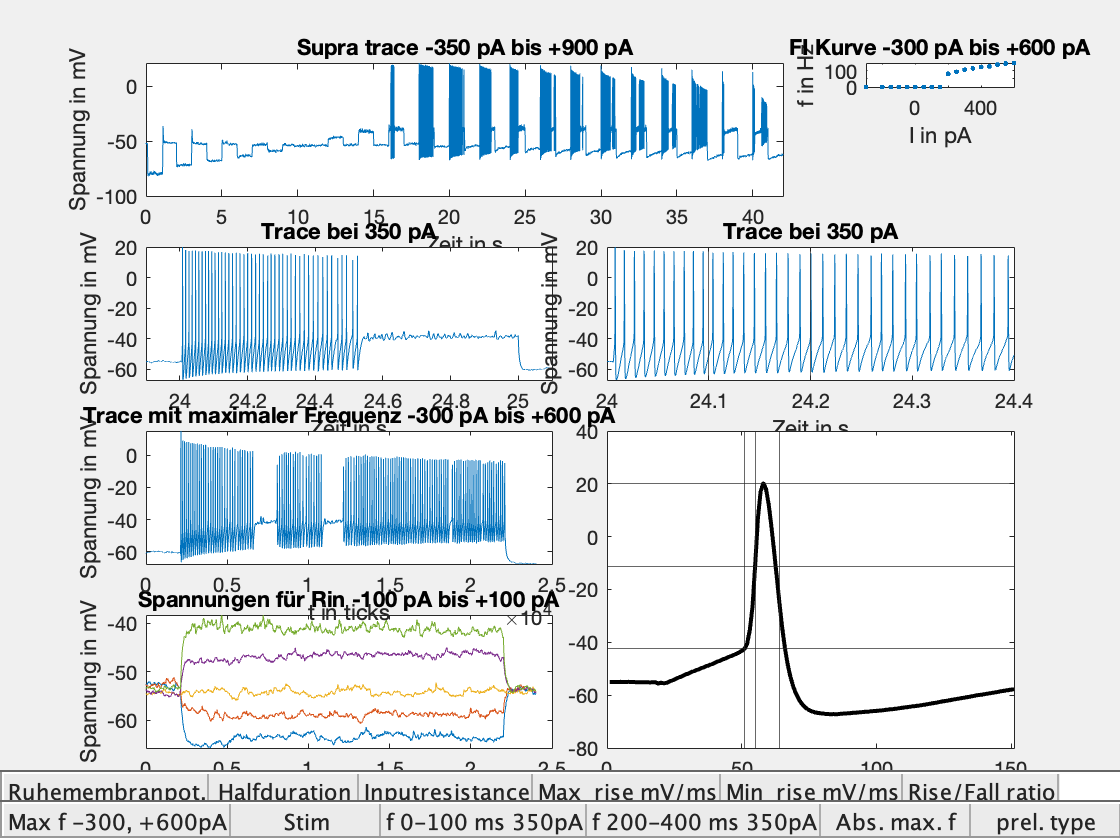

k = 21

k= 1;
for i= 1: size(all_data,2)
    for channel_n = 1:10 %durch alle 10 channel iterieren
        if all_data(i).docutables{channel_n,2} ==1
            data=all_data(i).supra(:,channel_n+1);
            stim_starts = [4.8e5, 5e5];
            stim_starts_before = [4.4e5, 4.6e5]; %to later test for freq in different stimulation timepoints
            stim_starts_after = [5.2e5, 5.4e5]; %to later test for freq in different stimulation timepoints
            %if i==2 && channel_n==8
            %    stim_starts = [4.805e5, 5e5];
            %end
            
            stim_duration = 1*20e3;
            trace_segment = data(stim_starts(1):stim_starts(2),1);
            % figure
            % plot(trace_segment)

            diff_trace_segment = diff(trace_segment);
            %downstroke in mV/ms
     
            
           
    
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>=diff_threshold, 1, "first");
            AP_time=AP_time
            
            max_downstroke_tik = min(diff_trace_segment);
            max_downstroke = max_downstroke_tik*20;
            if isempty(AP_time) == 1
                tcell.downstroke_mVperms(k) = 0;
            elseif AP_time > 0
                tcell.downstroke_mVperms(k) = max_downstroke;
            end

                        %upstroke in mV/ms
     
      
           
            max_upstroke_tik = max(diff_trace_segment);
            max_upstroke = max_upstroke_tik*20;
            if isempty(AP_time) == 1
                tcell.upstroke_mVperms(k) = 0;
            elseif AP_time > 0
                tcell.upstroke_mVperms(k) = max_upstroke;
            end
           
            % figure
            % % plot(diff_trace_segment, 'o')
            % % yline(2)
            % try
            % xline(AP_time)
            % end

            %extract the AP
            try
            if AP_time < 50
            trace_AP = trace_segment(1:AP_time+100);
            else
            trace_AP = trace_segment(AP_time-50:AP_time+100);
            end
            tcell.AP_time(k)=AP_time;
            end
            %threshold amplitude
            try
            threshold_timpoint = find(diff(trace_AP)>diff_threshold, 1, 'first');
            tcell.threshold_timpoint(k)=threshold_timpoint;
            threshold_amplitude = trace_AP(threshold_timpoint);
            tcell.threshold_amplitude(k)=threshold_amplitude;
            end

            %get the peak amplitude
            try
            peak_amplitude = max(trace_AP);
            tcell.peak_amplitude(k) = peak_amplitude;

            %AP amplitude
            ap_amplitude = peak_amplitude-threshold_amplitude;
            tcell.AP_Amplitude(k)=ap_amplitude;
            end
            %resting membrane pot
            resting_trace = data((stim_starts(1)-20000):(stim_starts(2)-20000),1);
            resting_pot = mean(resting_trace);
            tcell.resting_pot(k)=resting_pot;

            %Hyperpolarisation
            try
            trace_AP_hyper_timeframe = trace_segment(AP_time-10:AP_time+100);
            hyperpolarisation = min(trace_AP_hyper_timeframe);
            tcell.hyperpolarisation(k)=hyperpolarisation;
            end

            %ap half duration:
            try
            half_amplitude = threshold_amplitude + (ap_amplitude/2);
            tcell.half_amplitude(k)=half_amplitude;
            first_crossing_of_half_amplitude = find(trace_AP>=half_amplitude,1,"first");
            first_negative_crossing_of_half_amplitude = ...
                find(trace_AP(first_crossing_of_half_amplitude:end)<=half_amplitude,1, "first") + first_crossing_of_half_amplitude;
            
            %half duration
            half_duration = first_negative_crossing_of_half_amplitude-first_crossing_of_half_amplitude;

            tcell.half_duration_ms(k)=half_duration/20;
            end
            

            %input resistance
            stim_current_starts = [1.2e5, 1.40e5];
            stim_current = [-100e-12, -50e-12, 0e-12, 50e-12, 100e-12];
            Rin_sum=0;
            Rins={};
            Rin_avg=0;
            baseline = 0;
            dV=0;
            steadystate =0;
            
            for stim_i = 1: 5
                if i ~= 3
                trace_segment_res = all_data(i).supra(stim_current_starts(1):stim_current_starts(2),channel_n+1);
                diff_trace_segment_res = diff(trace_segment_res);
                diff_threshold = 2;
                AP_time_res = find(diff_trace_segment_res>diff_threshold, 1, "first");

                steadystate=mean(trace_segment_res);
                basesegment=(all_data(i).supra((stim_current_starts(1)-20000):(stim_current_starts(2)-20000),channel_n+1));
                baseline=mean(basesegment);
                stim_current_starts = stim_current_starts + [0.4e5, 0.4e5]
                dV=(steadystate-baseline);
                Rin=(dV)*10^-3/stim_current(stim_i);
                Rins=[Rins, Rin];
                Rin_sum=Rin_sum+Rin;
                end

                
                

            end
            Rin_avg=Rin_sum/(stim_i-1)
            %Tabele mit input resistances pro manip.
            Rins;
            tcell.input_resistance(k)=Rin_avg;

            %freq
            % figure
            % plot(trace_segment)

            stim_starts_1 = [1, 0.2e5];
            stim_starts_2 = [0.4e5, 0.6e5];
            stim_starts_3 = [0.8e5, 1e5];
            stim_starts_4 = [1.2e5, 1.4e5];
            stim_starts_5 = [1.6e5, 1.8e5];
            stim_starts_55 = [2e5, 2.2e5];
            stim_starts_6 = [2.4e5, 2.6e5];
            stim_starts_7 = [2.8e5, 3e5];
            stim_starts_8 = [3.2e5, 3.4e5];
            stim_starts_9 = [3.6e5, 3.8e5];
            stim_starts_10 = [4e5, 4.2e5];
            stim_starts_11 = [5.6e5, 5.8e5];
            stim_starts_12 = [6e5, 6.2e5];
            stim_starts_13 = [6.4e5, 6.6e5];
            stim_starts_14 = [6.8e5, 7e5];
            stim_starts_15 = [7.2e5, 7.4e5];
            stim_starts_16 = [7.6e5, 7.8e5];
            stim_starts_17 = [8e5, 8.2e5];
      

%-300pA
             
             
            trace_segment = data(stim_starts_1(1):stim_starts_1(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_1(1)+AP_time_freq:stim_starts_1(2),1);
                stim_starts_1(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number>2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_minus300pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_minus300pA_0ms_100ms(k)= Ap_number;
            end 
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_1(1)+AP_time_freq:stim_starts_1(2),1);
                 stim_starts_1(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number>2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_minus300pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_minus300pA_200ms_400ms(k)=Ap_number;
            end
            end

            %-200pA
            
             
            trace_segment = data(stim_starts_2(1):stim_starts_2(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_2(1)+AP_time_freq:stim_starts_2(2),1);
                stim_starts_2(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number >2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_minus200pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_minus200pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_2(1)+AP_time_freq:stim_starts_2(2),1);
                 stim_starts_2(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_minus200pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_minus200pA_200ms_400ms(k)=Ap_number;
            end
            end

            %-150pA
             
             
            trace_segment = data(stim_starts_3(1):stim_starts_3(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_3(1)+AP_time_freq:stim_starts_3(2),1);
                stim_starts_3(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_minus150pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_minus150pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_3(1)+AP_time_freq:stim_starts_3(2),1);
                 stim_starts_3(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_minus150pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_minus150pA_200ms_400ms(k)=Ap_number;
            end
            end

            %-100pA
             
             
            trace_segment = data(stim_starts_4(1):stim_starts_4(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_4(1)+AP_time_freq:stim_starts_4(2),1);
                stim_starts_4(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_minus100pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_minus100pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_4(1)+AP_time_freq:stim_starts_4(2),1);
                 stim_starts_4(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_minus100pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_minus100pA_200ms_400ms(k)=Ap_number;
            end
            end
            %-50pA
             
             
            trace_segment = data(stim_starts_5(1):stim_starts_5(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_5(1)+AP_time_freq:stim_starts_5(2),1);
                stim_starts_5(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_minus50pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_minus50pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_5(1)+AP_time_freq:stim_starts_5(2),1);
                 stim_starts_5(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_minus50pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_minus50pA_200ms_400ms(k)=Ap_number;
            end
            end






           %0pA
             
             
            trace_segment = data(stim_starts_55(1):stim_starts_55(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_55(1)+AP_time_freq:stim_starts_55(2),1);
                stim_starts_55(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_0pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_0pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_55(1)+AP_time_freq:stim_starts_55(2),1);
                 stim_starts_55(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_0pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_0pA_200ms_400ms(k)=Ap_number;
            end
            end


  







  

             % 50 pA
             
            trace_segment = data(stim_starts_6(1):stim_starts_6(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_6(1)+AP_time_freq:stim_starts_6(2),1);
                stim_starts_6(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_50pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_50pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_6(1)+AP_time_freq:stim_starts_6(2),1);
                 stim_starts_6(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_50pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_50pA_200ms_400ms(k)=Ap_number;
            end
            end


            %100
             
            trace_segment = data(stim_starts_7(1):stim_starts_7(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_7(1)+AP_time_freq:stim_starts_7(2),1);
                stim_starts_7(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_100pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_100pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_7(1)+AP_time_freq:stim_starts_7(2),1);
                 stim_starts_7(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_100pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_100pA_200ms_400ms(k)=Ap_number;
            end
            end


            %150
             
            trace_segment = data(stim_starts_8(1):stim_starts_8(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_8(1)+AP_time_freq:stim_starts_8(2),1);
                stim_starts_8(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_150pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_150pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_8(1)+AP_time_freq:stim_starts_8(2),1);
                 stim_starts_8(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_150pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_150pA_200ms_400ms(k)=Ap_number;
            end
            end


            %200
             
            trace_segment = data(stim_starts_9(1):stim_starts_9(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_9(1)+AP_time_freq:stim_starts_9(2),1);
                stim_starts_9(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_200pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_200pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_9(1)+AP_time_freq:stim_starts_9(2),1);
                 stim_starts_9(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_200pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_200pA_200ms_400ms(k)=Ap_number;
            end
            end



            %250

             
            trace_segment = data(stim_starts_10(1):stim_starts_10(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_10(1)+AP_time_freq:stim_starts_10(2),1);
                stim_starts_10(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_250pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_250pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_10(1)+AP_time_freq:stim_starts_10(2),1);
                 stim_starts_10(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_250pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_250pA_200ms_400ms(k)=Ap_number;
            end
            end

           
            % 300 pA
             
            trace_segment_before = data(stim_starts_before(1):stim_starts_before(2),1);
            diff_trace_segment_before = diff(trace_segment_before);
            diff_threshold = 2;
            AP_time_before = find(diff_trace_segment_before>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time_before;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment_before = data(stim_starts_before(1)+AP_time_freq:stim_starts_before(2),1);
                stim_starts_before(1)+AP_time_freq;
                diff_freq_segment_before = diff(freq_segment_before);
                AP_time_freq = AP_time_freq+find(diff_freq_segment_before>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_300pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_300pA_0ms_100ms(k)= Ap_number;
            end 
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment_before = data(stim_starts_before(1)+AP_time_freq:stim_starts_before(2),1);
                 stim_starts_before(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment_before);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment_before>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number >2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_300pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_300pA_200ms_400ms(k)=Ap_number;
            end
            end

            % 350 pA
             
            trace_segment = data(stim_starts(1):stim_starts(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts(1)+AP_time_freq:stim_starts(2),1);
                stim_starts(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_350pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_350pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts(1)+AP_time_freq:stim_starts(2),1);
                 stim_starts(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_350pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_350pA_200ms_400ms(k)=Ap_number;
            end
            end



            % 400 pA
            trace_segment_after = data(stim_starts_after(1):stim_starts_after(2),1);
            diff_trace_segment_after = diff(trace_segment_after);
            diff_threshold = 2;
            AP_time_after = find(diff_trace_segment_after>diff_threshold, 1, "first");


try
            Ap_number=0;
            First_AP_Time=AP_time_after;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment_after = data(stim_starts_after(1)+AP_time_freq:stim_starts_after(2),1);
                stim_starts_after(1)+AP_time_freq;
                diff_freq_segment_after = diff(freq_segment_after);
                AP_time_freq = AP_time_freq+find(diff_freq_segment_after>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_400pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_400pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment_after = data(stim_starts_after(1)+AP_time_freq:stim_starts_after(2),1);
                 stim_starts_after(1)+AP_time_freq;
                 diff_freq_segment_after = diff(freq_segment_after);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment_after>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_400pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_400pA_200ms_400ms(k)=Ap_number;
            end
            end
            %450
             
             
            trace_segment = data(stim_starts_11(1):stim_starts_11(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_11(1)+AP_time_freq:stim_starts_11(2),1);
                stim_starts_11(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_450pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_450pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_11(1)+AP_time_freq:stim_starts_11(2),1);
                 stim_starts_11(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_450pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_450pA_200ms_400ms(k)=Ap_number;
            end
            end

            %500
            
             
            trace_segment = data(stim_starts_12(1):stim_starts_12(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_12(1)+AP_time_freq:stim_starts_12(2),1);
                stim_starts_12(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_500pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_500pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_12(1)+AP_time_freq:stim_starts_12(2),1);
                 stim_starts_12(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_500pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_500pA_200ms_400ms(k)=Ap_number;
            end
            end

            %550
            
             
            trace_segment = data(stim_starts_13(1):stim_starts_13(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_13(1)+AP_time_freq:stim_starts_13(2),1);
                stim_starts_13(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_550pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_550pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_13(1)+AP_time_freq:stim_starts_13(2),1);
                 stim_starts_13(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_550pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_550pA_200ms_400ms(k)=Ap_number;
            end
            end



            %600
             
            trace_segment = data(stim_starts_14(1):stim_starts_14(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_14(1)+AP_time_freq:stim_starts_14(2),1);
                stim_starts_14(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_600pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_600pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_14(1)+AP_time_freq:stim_starts_14(2),1);
                 stim_starts_14(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_600pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_600pA_200ms_400ms(k)=Ap_number;
            end
            end

           %700
           trace_segment = data(stim_starts_15(1):stim_starts_15(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_15(1)+AP_time_freq:stim_starts_15(2),1);
                stim_starts_15(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_700pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_700pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_15(1)+AP_time_freq:stim_starts_15(2),1);
                 stim_starts_15(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_700pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_700pA_200ms_400ms(k)=Ap_number;
            end
            end
            
            %800
            trace_segment = data(stim_starts_16(1):stim_starts_16(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_16(1)+AP_time_freq:stim_starts_16(2),1);
                stim_starts_16(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_800pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_800pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_16(1)+AP_time_freq:stim_starts_16(2),1);
                 stim_starts_16(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_800pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_800pA_200ms_400ms(k)=Ap_number;
            end
            end

            %900
            trace_segment = data(stim_starts_17(1):stim_starts_17(2),1);
            diff_trace_segment = diff(trace_segment);
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");

try
            Ap_number=0;
            First_AP_Time=AP_time;

            AP_time_freq=0;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts_17(1)+AP_time_freq:stim_starts_17(2),1);
                stim_starts_17(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end
            end

            %tik in sekunde

            
            try
            if Ap_number > 2
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_900pA_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_900pA_0ms_100ms(k)= Ap_number;
            end
            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts_17(1)+AP_time_freq:stim_starts_17(2),1);
                 stim_starts_17(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
            end
            if Ap_number > 2
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_900pA_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_900pA_200ms_400ms(k)=Ap_number;
            end
            end



            % OUTPUT PLOTS
            i
            k
            channel_n
            clf
            trace_segment = all_data(i).supra(:,channel_n+1);
            time_segment = all_data(i).supra(:,1);
            stim_segment=trace_segment(4.8e5:5e5,:);
            
            subplot(4,4,[1:3])
            
            plot(time_segment, trace_segment)
            title('Supra trace -350 pA bis +900 pA')
            xlim([0 42])
            xlabel("Zeit in s"+newline+"   "+newline+"   "+newline+"   "+newline+"   ")
            ylabel("Spannung in mV")
            
            subplot(4,4,[5,6])
            plot(time_segment(4.78e5:5.02e5,:),trace_segment(4.78e5:5.02e5,:))
            title("Trace bei 350 pA")
            xlabel("Zeit in s"+newline+"   "+newline+"   "+newline+"   ")
            ylabel("Spannung in mV")
            
            subplot(4,4,[7,8])
            plot(time_segment(4.8e5:4.88e5,:),trace_segment(4.8e5:4.88e5,:))
            title("Trace bei 350 pA")
            xlabel("Zeit in s"+newline+"   "+newline+"   "+newline+"   ")
            ylabel("Spannung in mV")
            xlim([24.000 24.400])
            xline(24.1)
            xline(24.2)
            
            %For test purposes
            diff_threshold = 2;
            AP_time = find(diff(stim_segment)>diff_threshold, 1, "first");
            if AP_time >= 50
            trace_AP = stim_segment(AP_time-50:AP_time+100)
            else
            trace_AP = stim_segment(1:AP_time+100)
            end
            subplot(4,4,[11,12,15,16])
            plot(trace_AP, "Color", "k", "LineWidth",2)
            try
            yline(threshold_amplitude)
            xline(threshold_timpoint)
            yline(peak_amplitude)
            yline(half_amplitude)
            xline(first_crossing_of_half_amplitude)
            xline(first_negative_crossing_of_half_amplitude)  
            first_negative_crossing_of_half_amplitude
            end

            %input resistance
            stim_current_starts = [1.18e5, 1.42e5];
            stim_current = [-100e-12, -50e-12, 0e-12, 50e-12, 100e-12];
            Rin_sum=0;
            Rins={};
            Rin_avg=0;
            baseline = 0;
            dV=0;
            steadystate =0;
            
            for stim_i = 1: 5
                trace_segment_res = all_data(i).supra(stim_current_starts(1):stim_current_starts(2),channel_n+1);
                

                steadystate=mean(trace_segment_res);
                basesegment=(all_data(i).supra((stim_current_starts(1)-20000):(stim_current_starts(2)-20000),channel_n+1));
                baseline=mean(basesegment);
                stim_current_starts = stim_current_starts + [0.4e5, 0.4e5]
                subplot(4,4,[13,14])
                title("Spannungen für Rin -100 pA bis +100 pA")
                xlabel("t in ticks"+newline+"   "+newline+"   "+newline+"   ")
                ylabel("Spannung in mV")
                plot((trace_segment_res))
                hold on
                stim_i
                

            end
            hold off
            
            %FI curve
            stims_fi = [-300, -200, -150, -100, -50, 0, 50, 100, 150, 200, 250,300,350,400,450,500,550,600];
            freqs=table2array(tcell(k,9:4:77))
            maxfreq_time =  find(freqs == max(freqs)) 
            maxfreq_time=maxfreq_time*40000
            
            max_freq_segment = trace_segment((maxfreq_time-2000):(maxfreq_time+22000))
            
            subplot(4,4,[9,10])
            plot(max_freq_segment)
            title("Trace mit maximaler Frequenz -300 pA bis +600 pA")
            xlabel("t in ticks"+newline+"   "+newline+"   "+newline+"   ")
            ylabel("Spannung in mV")
            
            
            subplot(4,4,[4])
            plot(stims_fi,freqs, ".")
            title("FI Kurve -300 pA bis +600 pA")
            xlabel("I in pA"+newline+"   "+newline+"   "+newline+"   ")
            ylabel("f in Hz") 


            %ADD Summary Pllt
            %fileSummary=uifigure('Name','File Summary','WindowState','normal','Visible','on',"Resize","off");
            
            rownames = {'Ruhemembranpot.', 'Halfduration', 'Inputresistance', 'Max_rise mV/ms', 'Min_rise mV/ms', 'Rise/Fall ratio'};
            %subplot(5, 4, [17:20]);
            t = table(tcell.resting_pot(k),tcell.half_duration_ms(k),(tcell.input_resistance(k)*10^-6),tcell.upstroke_mVperms(k), tcell.downstroke_mVperms(k), abs(tcell.upstroke_mVperms(k)/tcell.downstroke_mVperms(k)), 'VariableNames', rownames);
            uit=uitable("Data",table2cell(t), "Position", [1 16 600 20],"FontSize",10);
            uit.ColumnName = rownames;
            uit.RowName=[];


            rownames2 = {'Max f -300, +600pA','Stim','f 0-100 ms 350pA', 'f 200-400 ms 350pA',"Abs. max. f", 'prel. type'};
            abs_max_freq =max(table2array(tcell(k,9:4:89)))
            if abs_max_freq >= 150
                type=char("fastspiking IN")
            elseif abs_max_freq >= 100  
                type=char("non fastspking IN")
            else

                type=char("undefined Neuron")
            end

           try
            t2 = {max(freqs),stims_fi(find(freqs == max(freqs))),(tcell.freq_Hz_350pA_0ms_100ms(k)),tcell.freq_Hz_350pA_200ms_400ms(k),abs_max_freq ,type};
            uit2=uitable("Data",t2, "Position", [1 1 600 20],"FontSize",10);
            uit2.ColumnName = rownames2;
            uit2.RowName=[];
           end 
  




            % filename_PLOT =  strcat("/Users/emiliathoma/Desktop/cell_plots_human/",tcell.cell_ID(k),"_cell_plot_human.pdf")
            % set(findobj(gcf,'type','axes'),'FontName','Arial','FontSize',8,'FontWeight','Bold', 'LineWidth', 1);
            % set(gcf, "Units", "centimeters");
            % screenposition = get(gcf, "Position");
            % set(gcf, ...
            %     "PaperPosition",[0 0 22 34], ...
            %     "PaperSize", [22 33]) 
            % 
            % print(gcf, filename_PLOT, "-dpdf", "-vector")
            







            k=k+1
            
        end
    end
end 

writetable(tcell,"/Users/emiliathoma/Desktop/results_supra_human_V5.csv" )

clf
test_view = all_data(5).supra(3.2e5:3.4e5,5)

test_view =    10.0708
    8.5144
    6.8665
    5.1880
    3.5095
    2.0752
    0.2441
   -1.5259
   -3.2043
   -4.8828


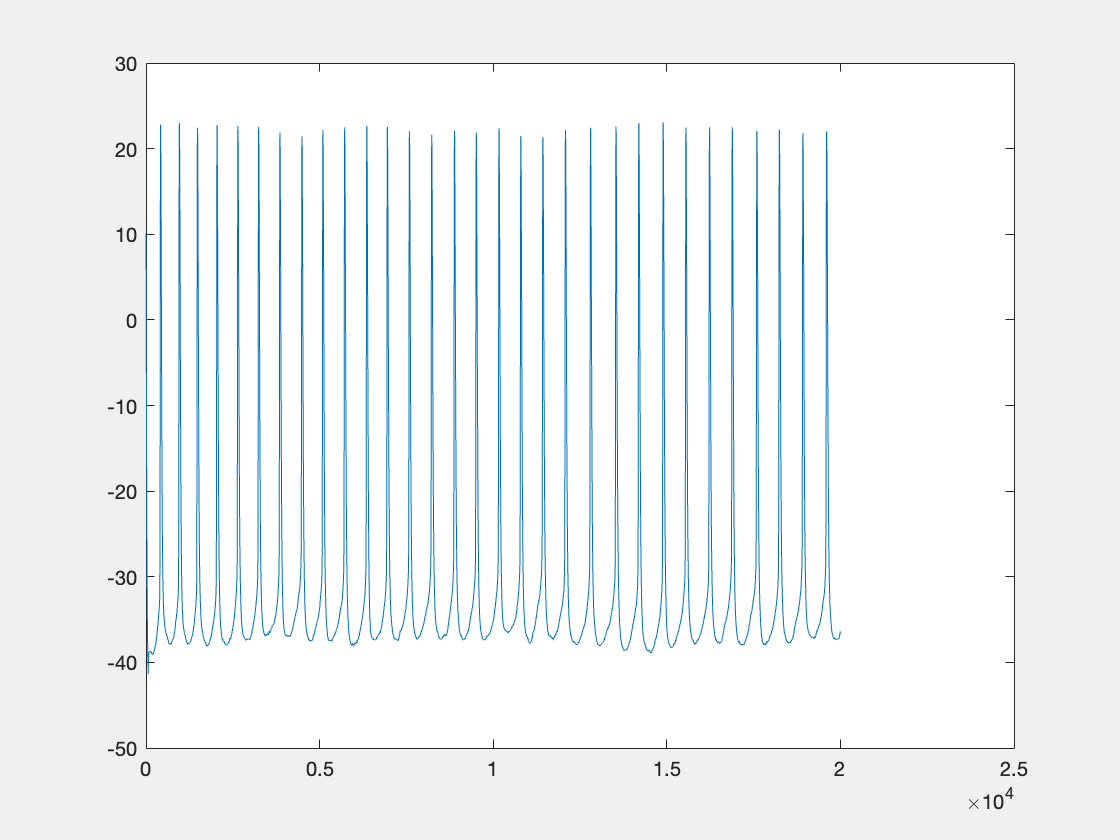

plot(test_view)

test_view = all_data(5).supra(:,5)
plot(test_view)

clearvars -except all_data

clf
cla
trace_segment = all_data(7).supra(:,5);                    
stim_segment=trace_segment(4.8e5:5e5,:);
channel_n = 4;
f=figure;
subplot(5,4,[1:3])
plot(trace_segment)
xlim([0 8.4e5])

subplot(5,4,[5,6])
plot(trace_segment(4.78e5:5.02e5,:))
subplot(5,4,[7,8])
plot(trace_segment(4.8e5:4.88e5,:))
xlim([0 8000])
xline(2000)
xline(2000)

%For test purposes
            diff_threshold = 2;
            AP_time = find(stim_segment>diff_threshold, 1, "first");
            trace_AP = stim_segment(AP_time-50:AP_time+100); 

subplot(5,4,[11,12,15,16])
            plot(trace_AP, "Color", "k", "LineWidth",2)
           
            yline(threshold_amplitude)
            xline(threshold_timpoint)
            yline(peak_amplitude)
            yline(half_amplitude)
            xline(first_crossing_of_half_amplitude)
            xline(first_negative_crossing_of_half_amplitude)   
            

            %input resistance
            stim_current_starts = [1.18e5, 1.42e5];
            stim_current = [-100e-12, -50e-12, 0e-12, 50e-12, 100e-12];
            Rin_sum=0;
            Rins={};
            Rin_avg=0;
            baseline = 0;
            dV=0;
            steadystate =0;
            
            for stim_i = 1: 5
                trace_segment_res = all_data(7).supra(stim_current_starts(1):stim_current_starts(2),channel_n+1);
                diff_trace_segment_res = diff(trace_segment_res);
                diff_threshold = 2;
                AP_time_res = find(diff_trace_segment_res>diff_threshold, 1, "first");

                steadystate=mean(trace_segment_res);
                basesegment=(all_data(7).supra((stim_current_starts(1)-20000):(stim_current_starts(2)-20000),channel_n+1));
                baseline=mean(basesegment);
                stim_current_starts = stim_current_starts + [0.4e5, 0.4e5]
                dV=(steadystate-baseline);
                Rin=(dV)*10^-3/stim_current(stim_i);
                Rins=[Rins, Rin];
                Rin_sum=Rin_sum+Rin;
                subplot(5,4,[13,14])
                plot((trace_segment_res))
                hold on
                stim_i
                

            end
            hold off
            
            
            Rin_avg=Rin_sum/stim_i

%FI curve
stims_fi = [-300, -200, -150, -100, -50, 0, 50, 100, 150, 200, 250,300,350,400,450,500,550,600];
freqs=table2array(tcell(17,9:4:77))
maxfreq_time =  find(freqs == max(freqs)) 
maxfreq_time=maxfreq_time*40000

max_freq_segment = trace_segment((maxfreq_time-2000):(maxfreq_time+22000))

subplot(5,4,[9,10])
plot(max_freq_segment)

diff_trace_segment_test= diff(max_freq_segment)


subplot(5,4,[4])
plot(stims_fi,freqs, ".")

% f=handle2struct(gcf)
% f=struct2handle(f, groot)
filename_PLOT =  strcat("/Users/emiliathoma/Desktop/",tcell.cell_ID(k),"_test2.pdf")
set(gcf, "Units", "centimeters");
screenposition = get(gcf, "Position");
set(gcf, ...
    "PaperPosition",[0 0 screenposition(3:4)], ...
    "PaperSize", [screenposition(3:4)])

print(gcf, filename_PLOT, "-dpdf", "-vector")

writetable(tcell,"/Users/emiliathoma/Desktop/results_supra_human_V5.csv" )

% data=all_data(27).supra(:,2)
% plot(data)
%             stim_starts = [4.8e5, 5e5]
% 
%             stim_duration = 1*20e3;
%             trace_segment = data(stim_starts(1):stim_starts(2),1)
%             figure
%             plot(trace_segment)
% 
%             diff_trace_segment = diff(trace_segment)
%             %downstroke in mV/ms
%             max_downstroke_tik = min(diff_trace_segment)
%             max_downstroke = max_downstroke_tik*20
%             diff_threshold = 2
%             AP_time = find(diff_trace_segment>diff_threshold, 1, "first")
            
